% Run params.m to retreive any parameters
params

% Load the simulink model 
sim('SingleMass.slx');
sim('MassSpring.slx');
sim('MassSpring_cancel_dynamics.slx');

set_param('SingleMass','SimMechanicsOpenEditorOnUpdate','off');
set_param('MassSpring','SimMechanicsOpenEditorOnUpdate','off');
set_param('MassSpring_cancel_dynamics','SimMechanicsOpenEditorOnUpdate','off');


testPoints = 50;
testOmega = zeros(testPoints, 1);
minOmega = 1; %1
maxOmega = 25; %25
multiplier = nthroot(maxOmega/minOmega, testPoints - 1);
for i = 1:testPoints
    testOmega(i) = minOmega * multiplier.^(i-1);
end

simTitle = 'MassSpring';
amplitude = 1;

set_param(strcat(simTitle, '/reference'),'Amplitude',string(amplitude));
energyArray     = zeros(length(testOmega), 1);
forceArray      = zeros(length(testOmega), 1);
refArray        = timeseries(length(testOmega), 1);
outputArray     = timeseries(length(testOmega), 1);

for i = 1:length(testOmega)
    set_param(strcat(simTitle, '/reference'),'Frequency',string(testOmega(i)));
    simOut = sim(simTitle,'ReturnWorkspaceOutputs','on');
    energyArray(i)  = simOut.energy.Data(end);
    forceArray(i)  = simOut.force.Data(end);
    refArray(i)     = simOut.ref;
    outputArray(i)  = simOut.pos;
end

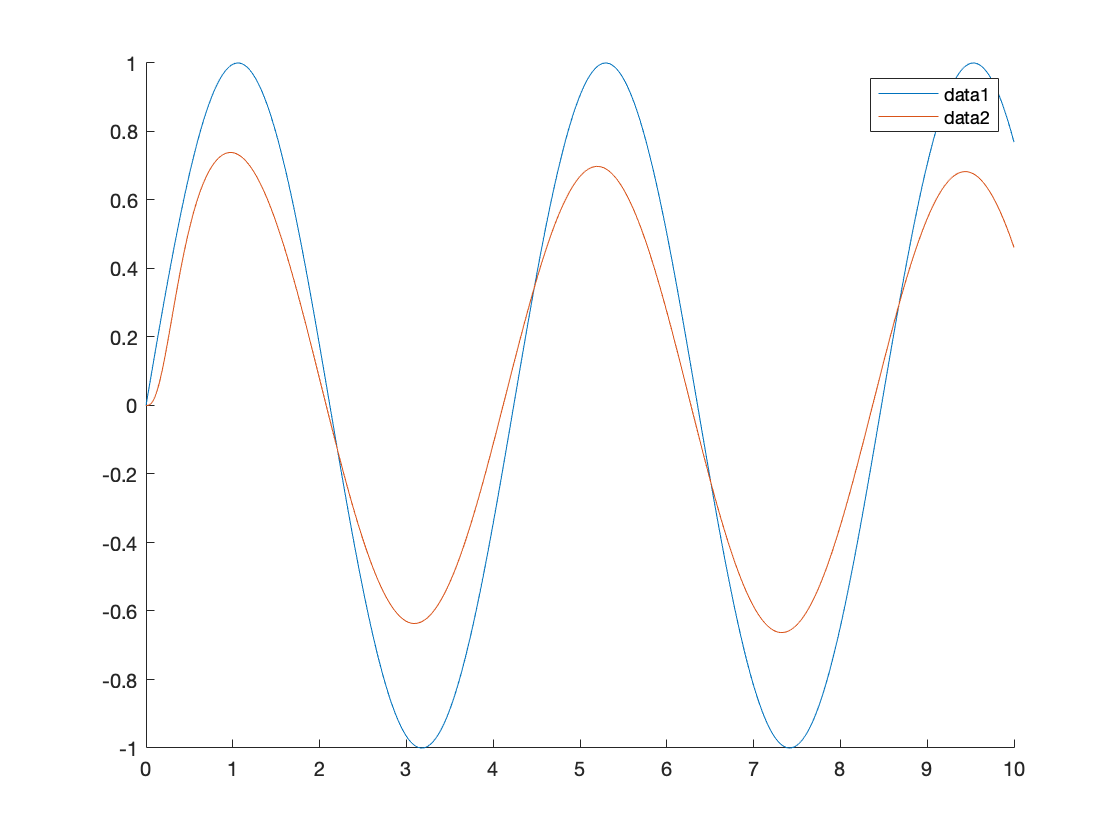

figure
hold on;
plot(refArray(7));
plot(outputArray(7));
legend();
hold off;

kp = round(str2double(get_param(strcat(simTitle, '/plant input'),'P')));
kd = round(str2double(get_param(strcat(simTitle, '/plant input'),'D')));
ki = round(str2double(get_param(strcat(simTitle, '/plant input'),'I')));

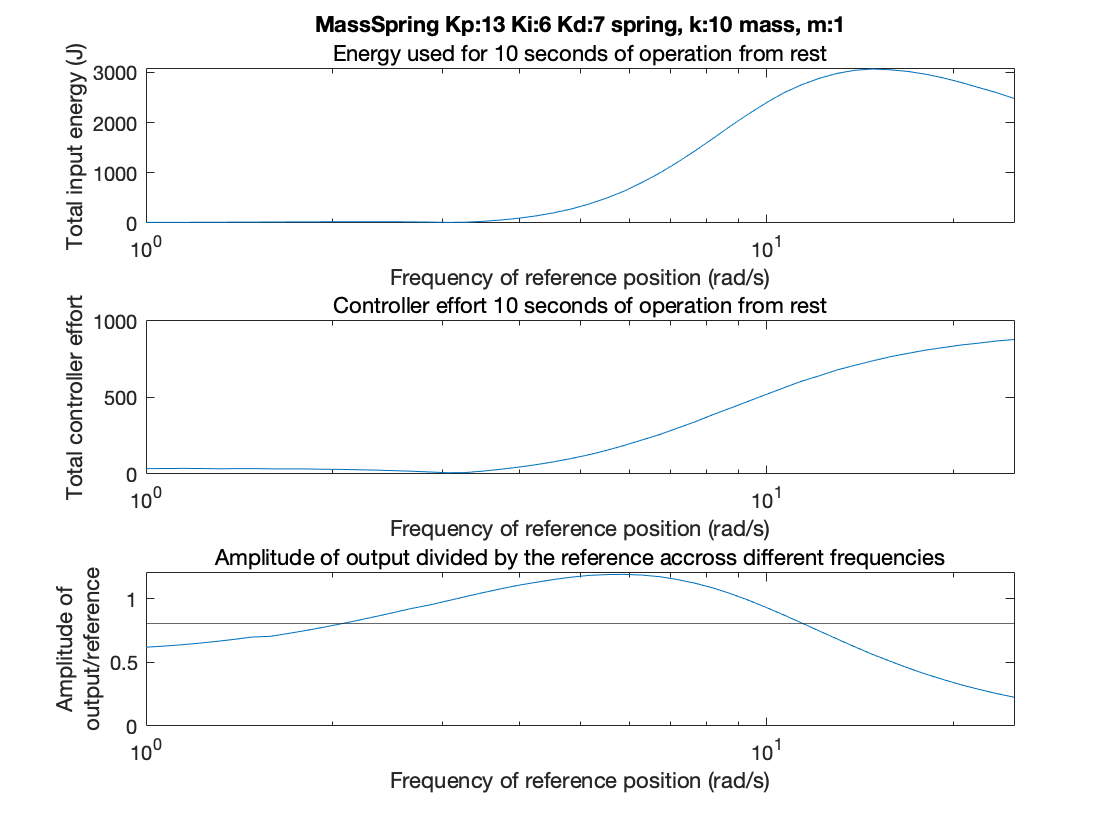


trackingArray   = zeros(length(testOmega), 1);
for i = 1:length(testOmega)
    trackingArray(i) = max(outputArray(i).Data(round(end/2):end))/amplitude;
end

subplot(3,1,1);
semilogx(testOmega, energyArray)
subtitle("Energy used for 10 seconds of operation from rest")
ylabel("Total input energy (J)")
xlabel("Frequency of reference position (rad/s)")
title(strcat(simTitle, " Kp:", string(kp), " Ki:", string(ki), ...
    " Kd:", string(kd), " spring, k:", string(k), " mass, m:",string(m)));

subplot(3,1,2);
semilogx(testOmega, forceArray)
ylabel("Total controller effort")
xlabel("Frequency of reference position (rad/s)")
subtitle("Controller effort 10 seconds of operation from rest");

subplot(3,1,3);
semilogx(testOmega, trackingArray)
hold on;
yline(amplitude *0.8);
yline(amplitude *1.2);
hold off;
ylabel({"Amplitude of","output/reference"});
xlabel("Frequency of reference position (rad/s)")
subtitle("Amplitude of output divided by the reference accross different frequencies");

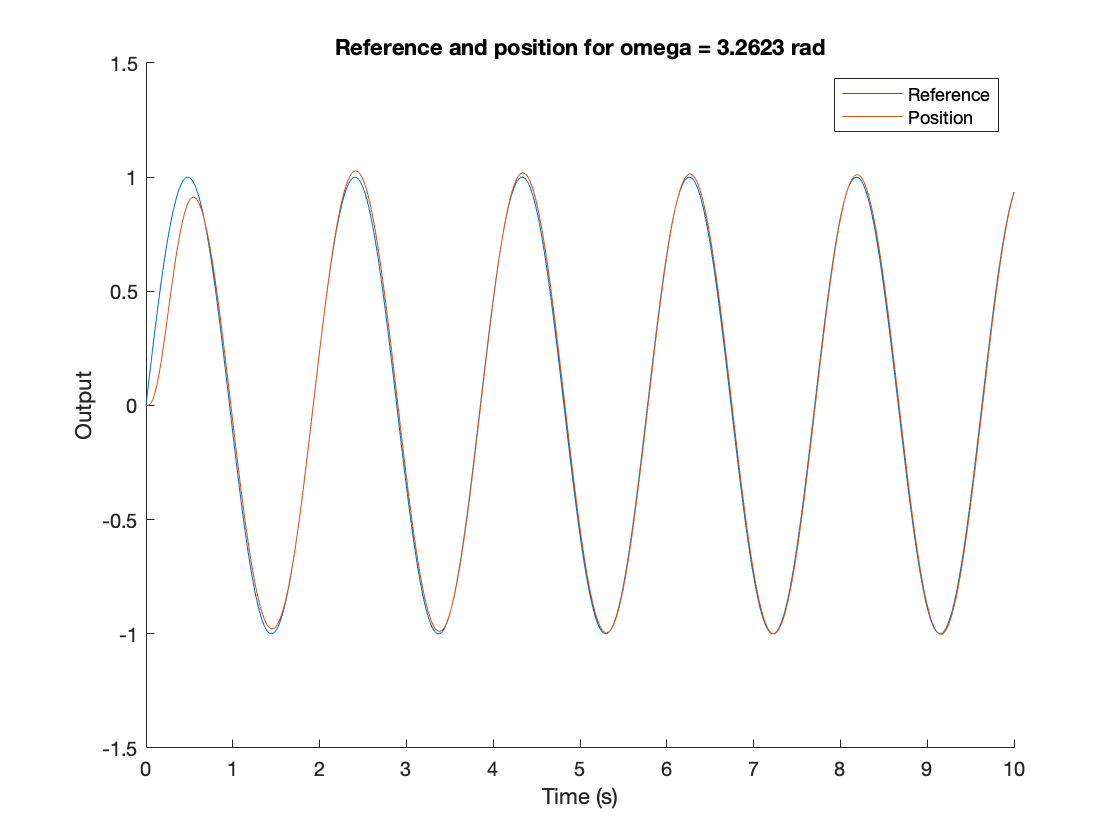

index = 19;
figure
hold on;
plot(refArray(index), "DisplayName", "Reference")
plot(outputArray(index), "DisplayName", "Position")
hold off;
legend;
xlabel("Time (s)");
ylabel("Output");
title(strcat("Reference and position for omega = ", string(testOmega(index)), " rad"));

## PID Tuning

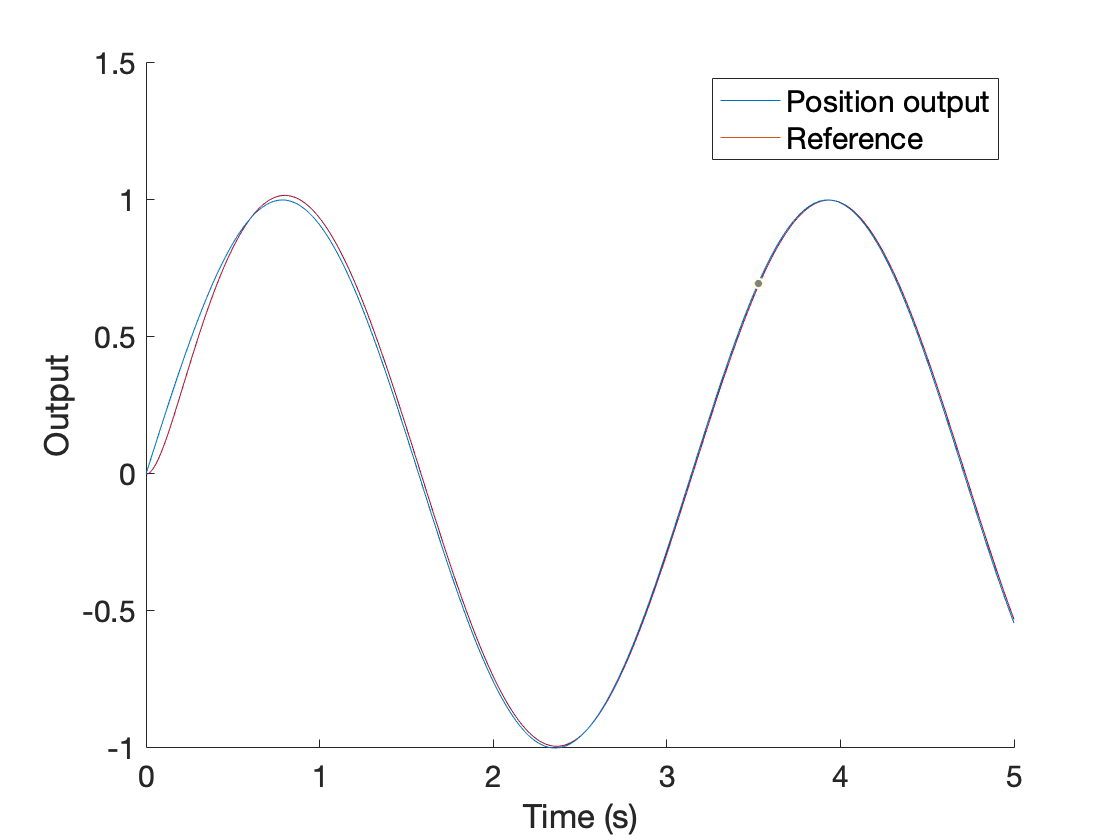

simTitle = 'MassSpring';
simOut = sim(simTitle);

hold on;
plot(simOut.pos);plot(simOut.ref);
hold off;
    
labelfont = 16;
legendfont = 15;
ticklabel = 15;

lgd = legend("Position output","Reference"); lgd.FontSize = legendfont;
xlabel("Time (s)", "Fontsize",labelfont); ylabel("Output","Fontsize",labelfont);
ylim auto
a = get(gca,'XTickLabel'); set(gca,'XTickLabel',a,'fontsize',ticklabel);

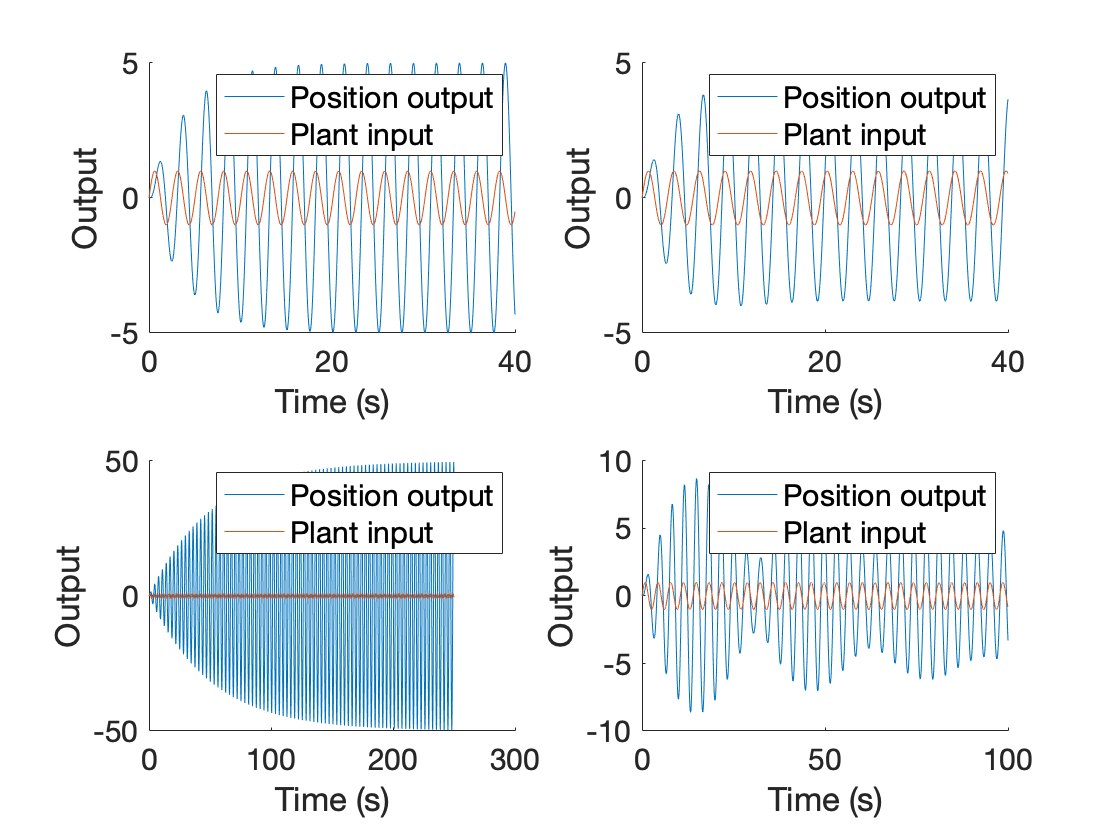

     1     0     0

w_n is equal to target
zeta is equal to target


     1     0     0

w_n is equal to target
zeta is equal to target


     1     0     0

w_n is equal to target
zeta is equal to target


     1     0     0

w_n is equal to target
zeta is equal to target


% Open Loop system probing
sim('openLoopExperiments.slx');
set_param('openLoopExperiments','SimMechanicsOpenEditorOnUpdate','off');

labelfont = 16;
legendfont = 15;
ticklabel = 15;
figure

zeta_setting = [0.1 0.1 0.01 0.01];
offset = [1 0.9 1 0.9];
Tf = [100 100 500 200];
for i = 1:4
    subplot(2,2,i);
    
    [m k c w_n zeta] = setVibrationParams(1, zeta_setting(i), [m k c], [0 1 1]);
    OL_omega = sqrt(k/m)*offset(i);
    simTitle = 'openLoopExperiments';
    set_param(strcat(simTitle, '/Plant input'),'Frequency',string(OL_omega));
    simOut = sim(simTitle,[0 Tf(i)]);
    
    hold on;
    plot(simOut.pos);plot(simOut.u);
    hold off;
        
    lgd = legend("Position output","Plant input"); lgd.FontSize = legendfont;
    xlabel("Time (s)", "Fontsize",labelfont); ylabel("Output","Fontsize",labelfont);
    a = get(gca,'XTickLabel'); set(gca,'XTickLabel',a,'fontsize',ticklabel);
end